# Opulent Voice Physical Layer 

adapted from fred harris script

Abraxas3d

## Physical Layer Summary from Opulent Voice Specification

OPV Protocol is 4FSK modulation with a deviation index of 0.5

It is designed to transmit 16 kbps OPUS voice encoded data so that we can enjoy high fidelity voice on the amateur radio bands where it is allowed. Opulent Voice has IP, UDP, and RTP headers to enable application layer programs to easily process voice or data. 

f_sym = 27,100 Sym/sec, (2-bits/symbol)

Bit 1   Bit 0    Symbol   4FSK Deviation  

     0       1        +3        +40650 kHz

     0       0        +1        +13550 kHz

     1       0        -1        -13550 kHz

     1       1        -3        -40650 kHz

   1 0    1 1    0 1    00    -1  -3  +3  +1

Frame duration is 40 msec.

Preamable is 40 msec of alternating +3 and -3 tones.

## IQ Modulation

If you are reading this and need a tutorial about IQ modulation, then an excellent one is here:

[https://www.youtube.com/watch?v=h_7d-m1ehoY](https://www.youtube.com/watch?v=h_7d-m1ehoY)

## Shaping Filters

Why do we use shaping filters? To use minimum bandwidth while eliminating inter-symbol interference.

An excellent tutorial can be found here:

[https://www.youtube.com/watch?v=NGzVJSLm0Kc](https://www.youtube.com/watch?v=NGzVJSLm0Kc)

### Transmit and Receive Filters

Using root raised cosine filters, let's set up some filters and calculate bit error rates.

clear
clf
% Filter rolloff
% The rolloff factor determines the excess bandwidth 
% of the filter. Zero rolloff corresponds to a 
% brick-wall filter and unit rolloff to a pure root
% raised cosine.
rolloff = 0.3

rolloff = 0.3000


% Center frequency of transmission
center_freq = 435e6

center_freq = 435000000


% Filter span in symbols
span = 10

span = 10


% samples per symbol used in transmit and receive filter
filter_sps = 10

filter_sps = 10


% samples per symbol used in modulator and/or demodulator
modulator_sps = filter_sps

modulator_sps = 10


% Modulation order
M = 4

M = 4


% bits per symbol
bits_per_symbol = log2(M)

bits_per_symbol = 2


% symbols in a frame
symbols_per_frame = 1084

symbols_per_frame = 1084


% bits in a frame
n = bits_per_symbol*symbols_per_frame

n = 2168


% frame duration in seconds is 40 mS
frame_duration = 0.04

frame_duration = 0.0400


% Symbol rate
Fsymbol = symbols_per_frame/frame_duration

Fsymbol = 27100


% frequency separation (spacing)
freq_sep = 0.5*Fsymbol

freq_sep = 13550


% Sample rate
Fs = filter_sps*Fsymbol

Fs = 271000


% Energy per bit over noise power in dB
EbNo = [-10:3:30]

EbNo =    -10    -7    -4    -1     2     5     8    11    14    17    20    23    26    29



txfilter = comm.RaisedCosineTransmitFilter( ...
    RolloffFactor=rolloff, ...
    FilterSpanInSymbols=span, ...
    OutputSamplesPerSymbol=filter_sps)

txfilter =   comm.RaisedCosineTransmitFilter with properties:

                     Shape: 'Square root'
             RolloffFactor: 0.3000
       FilterSpanInSymbols: 10
    OutputSamplesPerSymbol: 10
                      Gain: 1



rxfilter = comm.RaisedCosineReceiveFilter( ...
    RolloffFactor=rolloff, ...
    FilterSpanInSymbols=span, ...
    InputSamplesPerSymbol=filter_sps, ...
    DecimationFactor=filter_sps)

rxfilter =   comm.RaisedCosineReceiveFilter with properties:

                    Shape: 'Square root'
            RolloffFactor: 0.3000
      FilterSpanInSymbols: 10
    InputSamplesPerSymbol: 10
         DecimationFactor: 10
         DecimationOffset: 0
                     Gain: 1



txCoef = coeffs(txfilter);
rxCoef = coeffs(rxfilter);

%fvtool(txfilter,Analysis="impulse")
% filter delay in bits. Group delay is half of the filter
% span through one filter, so the entire delay is one filter
% span through two. Span times bits per symbol to get bits.
filtDelay = bits_per_symbol*span

filtDelay = 20


% Create an error rate counter System object. 
% Set the ReceiveDelay property to account 
% for the delay through the matched filters.
errorRate = comm.ErrorRate(ReceiveDelay=2, Samples="Entire frame")

errorRate =   comm.ErrorRate with properties:

        ReceiveDelay: 2
    ComputationDelay: 0
             Samples: 'Entire frame'
      ResetInputPort: false



% create some bits! This is input data.
% note the use of the modulation order 
% if we needed it in integer form.
%x = randi([0 M-1],n,1)
data_in = randi([0 1],10*bits_per_symbol*symbols_per_frame,1);

% modulate our signal with FSK
our_modulator = comm.FSKModulator(M,freq_sep,Fsymbol,"BitInput",true, "SamplesPerSymbol",modulator_sps)

our_modulator =   comm.FSKModulator with properties:

        ModulationOrder: 4
               BitInput: true
          SymbolMapping: 'Gray'
    FrequencySeparation: 13550
        ContinuousPhase: true
       SamplesPerSymbol: 10
             SymbolRate: 27100
         OutputDataType: 'double'


modSig = our_modulator(data_in);

% transmit our signal
txSig = txfilter(modSig);

% let's look at the signal
specAnal1 = spectrumAnalyzer(SampleRate=Fs,Name="Modulated Signal", YLimits=[-60,25]);
specAnal2 = spectrumAnalyzer(SampleRate=Fs*filter_sps,Name="Transmitted Signal through Channels",FrequencySpan="start-and-stop-frequencies", StartFrequency=-100000, StopFrequency=100000, YLimits=[-60,25]);
specAnal3 = spectrumAnalyzer(SampleRate=Fs,Name="After Receive Filter from Channels (Modulated for Comparison)",FrequencySpan="start-and-stop-frequencies", StartFrequency=-100000, StopFrequency=100000, YLimits=[-60,25]);

figure(2)
specAnal1(modSig)


How does SNR and EbNo relate?

We see this equation a lot.

SNR = EbNo + 10log10(codeRate) + 10log10(bitsPerSymbol) - 10log10(sps) 

see [https://www.dsprelated.com/showarticle/168.php](https://www.dsprelated.com/showarticle/168.php) for the one below

SNR = Eb/No + 10log(codeRate) + 10log(symbolRate) + 10log(bitsPerSymbol)  - 10log(noiseBandwidth)

How did we get this?

Noise bandwidth: In a calibrated noise bench test this number may be adjusted to account for the shape of the noise spectrum to provide the normalized noise bandwidth. In a simulation this is usually proportional to the assumed sampling rate.

Uncoded, so codeRate = 1. Set noiseBandwith to the sample rate.

SNR = Eb/No + 10log(1) + 10log(symbolRate) + 10log(bitsPerSymbol)  - 10log(sampleRate)

Re-order. Log(1) = 0, so drop out the codeRate term.

SNR = Eb/No + 10log(bitsPerSymbol) + 10log(symbolRate)   - 10log(sampleRate)

Using quotient rule. We're looking for samples per symbol. Re-order.

SNR = Eb/No + 10log(bitsPerSymbol) - ( - 10log(symbolRate)   + 10log(sampleRate) )

SNR = Eb/No + 10log(bitsPerSymbol) - (10log(sampleRate) - 10log(symbolRate))

SNR = Eb/No + 10log(bitsPerSymbol) - (10log(sampleRate/symbolRate))

SNR = Eb/No + 10log(bitsPerSymbol) - 10log(samplesPerSymbol)

This now matches the examples from Mathworks. Why do we do this?

We have to increase the SNR by how many information bits are being sent per symbol. Eb/No is normalized to a herz but SNR is signal power over noise power and the amount of time the signal is being transmitted matters. 

We reduce SNR by the number of samples per symbol. Why? We treat the noise bandwidth as equal to the sampling rate. We've increased the sample rate by interpolating in the transmit filter, so we are letting in more noise, and this drives down our SNR. 

How do we determine the proper number of samples per symbol? We can use the aliasing criterion. Based on our pulse shape, we know what the total bandwidth of the shaped signal will be. Select an oversampling factor that yields a sample rate that is above the Nyquist rate and we will be fine. 

Eb is the energy in a bit. No is the noise power in one Hertz bandwidth.

"isn't SNR same as EbNo?" They are not exactly the same, but are related and used for similar purposes. Think about trying to send a weak signal over a noisy channel by amplitude shifting. In an extreme case, your instantaneous signal amplitude may be substantially smaller than the RMS amplitude of your noise. This implies that your SNR in dB is negative. However, we can still get information through if we really slow down our symbol rate, staying at one amplitude for a really long time. We take a long average over one symbol period, which should get largely positive due to the signal, but the noise should average out to zero. However, staying at one amplitude for a long time takes more energy than just sending a short blip, and so that requires more signal energy per bit to send. Normalizing this signal energy by the noise we are trying to overcome gives us Eb/No. So, we can have an instantaneous SNR of something like -3 dB, yet still end up with an Eb/No > 10 dB and close the link for communication. So, they are not the same, yet still measure the strength of the signal to the strength of the noise.

the subtraction of 10*log10(sps) is because we want to lower the SNR by 10 samples per symbol becuase the receiver will be raising it up by this amount using the receive filter. 

The 10*log10(bits per symbol) term can be thought of as

10*log10(fb/B) which is information rate fb to the channel bandwidth B, i.e., the ratio R = fb/B.

Information rate is how many bits per second are being passed over the channel. For us, it's 54,200 bits per second. Channel bandwidth is the sampling rate? of 271000 samples per second? 

10*log10(54200/271000) bits per symbol. 

So where does the oversampling by a factor of 10 show up? Just in the samples per symbol term? This only catches the transmit filter and not the 10 samples per symbol in the modulator.

% Calculate the signal-to-noise ratio (SNR) 
% in dB given EbNo. Pass the transmitted 
% signal through the AWGN channel using
% either the awgnchannel system object.

SNR = EbNo + 10*log10(bits_per_symbol) - 10*log10(filter_sps);

noisySigCollection = [];

% build a collection of transmitted signals
% to run through the channel at different SNRs.
txSigCollection = repmat(txSig,1,length(SNR));

% run the channel model on the entire collection all at once.
awgnchan = comm.AWGNChannel("NoiseMethod","Signal to noise ratio (SNR)","SNR",SNR)

awgnchan =   comm.AWGNChannel with properties:

     NoiseMethod: 'Signal to noise ratio (SNR)'
             SNR: [-16.9897 -13.9897 -10.9897 -7.9897 -4.9897 -1.9897 1.0103 4.0103 7.0103 10.0103 13.0103 16.0103 19.0103 22.0103]
     SignalPower: 1
    RandomStream: 'Global stream'


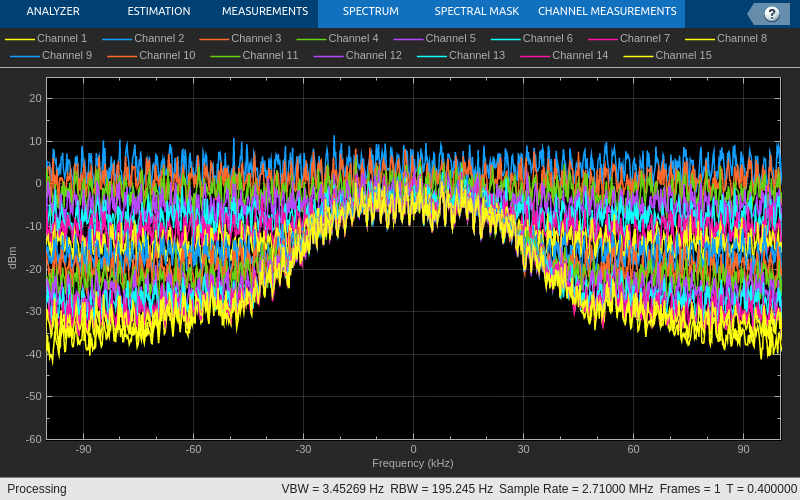

noisySigCollection = awgnchan(txSigCollection);

%plot(noisySigCollection)

figure(3)
specAnal2(txSig, noisySigCollection)



rxSig = [];

% Filter the noisy signals
for i = 1:size(EbNo,2);
    rxSig = [rxSig rxfilter(noisySigCollection(:,i))];
end

figure(4)
specAnal3(modSig, rxSig)


% create FSK demodulator
our_demodulator = comm.FSKDemodulator(M,freq_sep,Fsymbol,"BitOutput",true,"SamplesPerSymbol", modulator_sps)

our_demodulator =   comm.FSKDemodulator with properties:

        ModulationOrder: 4
              BitOutput: true
          SymbolMapping: 'Gray'
    FrequencySeparation: 13550
       SamplesPerSymbol: 10
             SymbolRate: 27100
         OutputDataType: 'double'



% FSK demodulate
data_out = [];
for i = 1:size(EbNo,2);
    data_out = [data_out our_demodulator(rxSig(:,i))];

end


% need to account for the filter delay to line up
% the transmitted data with the demodulated data

data_out_aligned = data_out;
data_out_aligned(1:2,:) = [];
data_in_aligned = data_in(1:end-2);

% BER is a ratio (scalar number)
[num,BER] = biterr(data_in_aligned,data_out_aligned)

num =        10127        9525        8266        6319        3738        1550         317          20           0           0           0           0           0           0


BER =     0.4672    0.4394    0.3813    0.2915    0.1724    0.0715    0.0146    0.0009         0         0         0         0         0         0



% attempt to use the error rate system object
BER_system_object = errorRate(data_in, data_out(:,7))

BER_system_object = 1.0e+04 *

    0.0000
    0.0317
    2.1678



% If your communications system uses several bits to 
% represent one symbol, counting symbol errors is 
% different from counting bit errors. In either the 
% symbol- or bit-counting case, the error rate is the 
% number of errors divided by the total number of 
% transmitted symbols or bits, respectively.
% See https://www.youtube.com/watch?v=MNEsnql14ko&ab_channel=NealPatwari

% BER_calculated comes from
% https://www.jmest.org/wp-content/uploads/JMESTN42353572.pdf

for i = 1:size(EbNo,2)
    BER_calculated(:,i) = erfc(sqrt(10^(EbNo(i)/10)));
end

figure(5)
semilogy(EbNo,BER,"LineWidth",2)

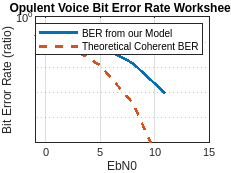

hold on
semilogy(EbNo,BER_calculated, "LineWidth",2,LineStyle="--")
hold off
legend('BER from our Model','Theoretical Coherent BER')
xlabel('EbN0')
ylabel('Bit Error Rate (ratio)')
ylim([10e-6 1])
xlim([-1 15])
title("Opulent Voice Bit Error Rate Worksheet")
grid